
%Simple Mass Spring Damper system

t = [0: 0.1: 99.9]

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000



springTf = tf([1], [10, 10, 10])

springTf =
 
          1
  ------------------
  10 s^2 + 10 s + 10
 
Continuous-time transfer function.




%Step Inputs

figure

inputStep1 = ones(1000,1)

inputStep1 =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


inputStep2 = 0.1 * ones(1000,1)

inputStep2 =     0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000


inputStep3 = [zeros(500,1);ones(500,1)]

inputStep3 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


inputStep4 = [ones(300,1);zeros(400,1);ones(300,1)]

inputStep4 =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


inputStep5 = -1 * ones(1000,1)

inputStep5 =     -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1


outputStep1 = lsim(springTf, inputStep1, t)

outputStep1 =          0
    0.0005
    0.0019
    0.0041
    0.0069
    0.0104
    0.0145
    0.0189
    0.0237
    0.0288


outputStep2 = lsim(springTf, inputStep2, t)

outputStep2 =    -0.0000
    0.0000
    0.0002
    0.0004
    0.0007
    0.0010
    0.0014
    0.0019
    0.0024
    0.0029


outputStep3 = lsim(springTf, inputStep3, t)

outputStep3 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


outputStep4 = lsim(springTf, inputStep4, t)

outputStep4 =          0
    0.0005
    0.0019
    0.0041
    0.0069
    0.0104
    0.0145
    0.0189
    0.0237
    0.0288


outputStep5 = lsim(springTf, inputStep5, t)

outputStep5 =          0
   -0.0005
   -0.0019
   -0.0041
   -0.0069
   -0.0104
   -0.0145
   -0.0189
   -0.0237
   -0.0288


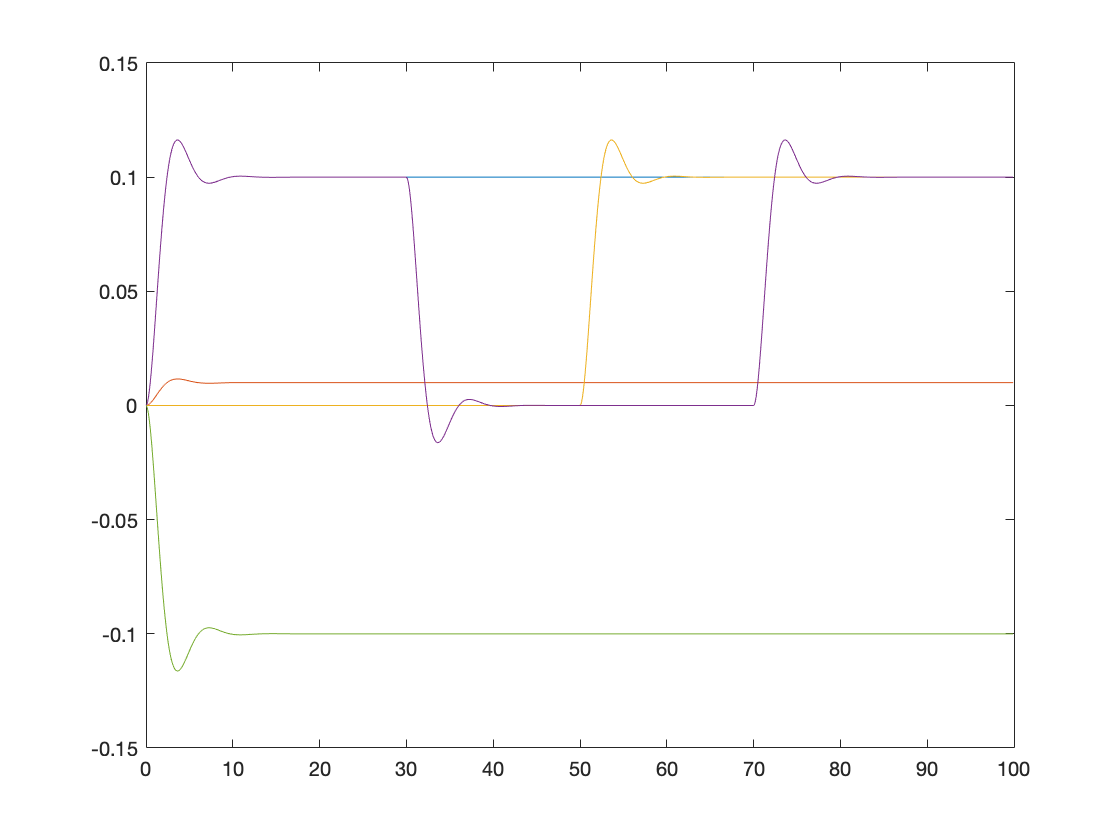

plot(t, [outputStep1, outputStep2, outputStep3, outputStep4, outputStep5])


subOut = vertcat([0], outputStep1);
subOut = subOut(1:end-1)

subOut =          0
         0
    0.0005
    0.0019
    0.0041
    0.0069
    0.0104
    0.0145
    0.0189
    0.0237



writematrix(horzcat(inputStep1, subOut), 'inputStep1.csv')
writematrix(outputStep1, 'outputStep1.csv')
%Sinusoidal Inputs


figure
inSine1 = @(t) 0.1*sin(t)

inSine1 = function_handle with value:
    @(t)0.1*sin(t)


inSine2 = @(t) cos(t)

inSine2 = function_handle with value:
    @(t)cos(t)


inSine3 = @(t) sin(t*0.1)

inSine3 = function_handle with value:
    @(t)sin(t*0.1)


inSine4 = @(t) 1 + sin(t)

inSine4 = function_handle with value:
    @(t)1+sin(t)


inSine5 = @(t) 0.1*sin(t)

inSine5 = function_handle with value:
    @(t)0.1*sin(t)


inputSine1 = inSine1(t)

inputSine1 =          0    0.0100    0.0199    0.0296    0.0389    0.0479    0.0565    0.0644    0.0717    0.0783    0.0841    0.0891    0.0932    0.0964    0.0985    0.0997    0.1000    0.0992    0.0974    0.0946    0.0909    0.0863    0.0808    0.0746    0.0675    0.0598    0.0516    0.0427    0.0335    0.0239    0.0141    0.0042   -0.0058   -0.0158   -0.0256   -0.0351   -0.0443   -0.0530   -0.0612   -0.0688   -0.0757   -0.0818   -0.0872   -0.0916   -0.0952   -0.0978   -0.0994   -0.1000   -0.0996   -0.0982


inputSine2 = inSine2(t)

inputSine2 =     1.0000    0.9950    0.9801    0.9553    0.9211    0.8776    0.8253    0.7648    0.6967    0.6216    0.5403    0.4536    0.3624    0.2675    0.1700    0.0707   -0.0292   -0.1288   -0.2272   -0.3233   -0.4161   -0.5048   -0.5885   -0.6663   -0.7374   -0.8011   -0.8569   -0.9041   -0.9422   -0.9710   -0.9900   -0.9991   -0.9983   -0.9875   -0.9668   -0.9365   -0.8968   -0.8481   -0.7910   -0.7259   -0.6536   -0.5748   -0.4903   -0.4008   -0.3073   -0.2108   -0.1122   -0.0124    0.0875    0.1865


inputSine3 = inSine3(t)

inputSine3 =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0699    0.0799    0.0899    0.0998    0.1098    0.1197    0.1296    0.1395    0.1494    0.1593    0.1692    0.1790    0.1889    0.1987    0.2085    0.2182    0.2280    0.2377    0.2474    0.2571    0.2667    0.2764    0.2860    0.2955    0.3051    0.3146    0.3240    0.3335    0.3429    0.3523    0.3616    0.3709    0.3802    0.3894    0.3986    0.4078    0.4169    0.4259    0.4350    0.4439    0.4529    0.4618    0.4706


inputSine4 = inSine4(t)

inputSine4 =     1.0000    1.0998    1.1987    1.2955    1.3894    1.4794    1.5646    1.6442    1.7174    1.7833    1.8415    1.8912    1.9320    1.9636    1.9854    1.9975    1.9996    1.9917    1.9738    1.9463    1.9093    1.8632    1.8085    1.7457    1.6755    1.5985    1.5155    1.4274    1.3350    1.2392    1.1411    1.0416    0.9416    0.8423    0.7445    0.6492    0.5575    0.4702    0.3881    0.3122    0.2432    0.1817    0.1284    0.0838    0.0484    0.0225    0.0063    0.0001    0.0038    0.0175


inputSine5 = inSine5(t)

inputSine5 =          0    0.0100    0.0199    0.0296    0.0389    0.0479    0.0565    0.0644    0.0717    0.0783    0.0841    0.0891    0.0932    0.0964    0.0985    0.0997    0.1000    0.0992    0.0974    0.0946    0.0909    0.0863    0.0808    0.0746    0.0675    0.0598    0.0516    0.0427    0.0335    0.0239    0.0141    0.0042   -0.0058   -0.0158   -0.0256   -0.0351   -0.0443   -0.0530   -0.0612   -0.0688   -0.0757   -0.0818   -0.0872   -0.0916   -0.0952   -0.0978   -0.0994   -0.1000   -0.0996   -0.0982


outputSine1 = lsim(springTf,inputSine1, t)

outputSine1 =          0
    0.0000
    0.0000
    0.0000
    0.0001
    0.0002
    0.0003
    0.0005
    0.0007
    0.0009


outputSine2 = lsim(springTf,inputSine2, t)

outputSine2 =          0
    0.0005
    0.0019
    0.0040
    0.0068
    0.0102
    0.0140
    0.0180
    0.0223
    0.0266


outputSine3 = lsim(springTf,inputSine3, t)

outputSine3 =          0
    0.0000
    0.0000
    0.0000
    0.0001
    0.0002
    0.0003
    0.0005
    0.0007
    0.0009


outputSine4 = lsim(springTf,inputSine4, t)

outputSine4 =          0
    0.0005
    0.0020
    0.0045
    0.0079
    0.0122
    0.0175
    0.0235
    0.0303
    0.0378


outputSine5 = lsim(springTf,inputSine5, t)

outputSine5 =          0
    0.0000
    0.0000
    0.0000
    0.0001
    0.0002
    0.0003
    0.0005
    0.0007
    0.0009


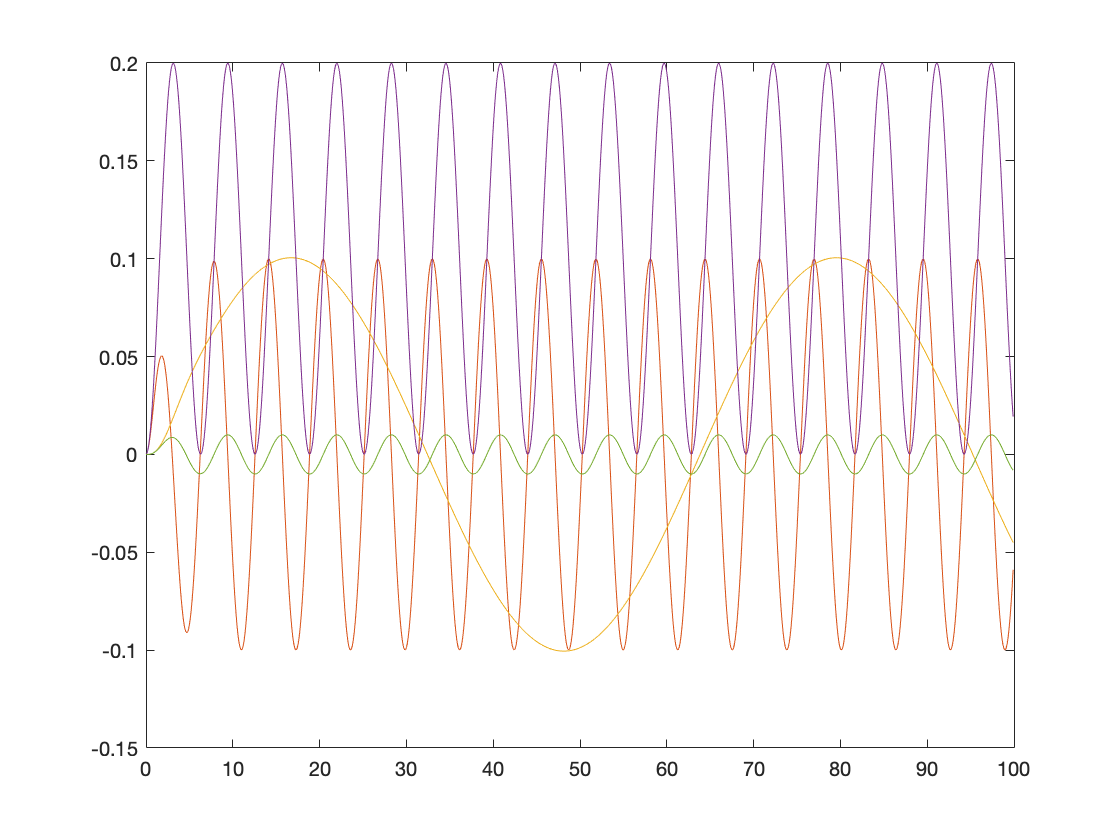

plot(t, [outputSine1, outputSine2, outputSine3, outputSine4, outputSine5])


subOut = vertcat([0], outputStep1);
subOut = subOut(1:end-1);

horzcatted = horzcat(inputStep1, subOut);
writematrix(horzcatted(1:100, :), 'inputStep1.csv')
writematrix(outputStep1(1:100, :), 'outputStep1.csv')